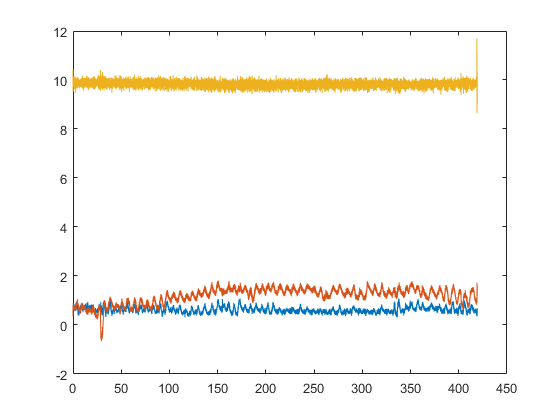

clear

filename = '7min_nathan_50hz.mat';
chunk_time = 60;
start_trim = 3;
[time,accel] = ChunkPlotData(filename,chunk_time,start_trim);

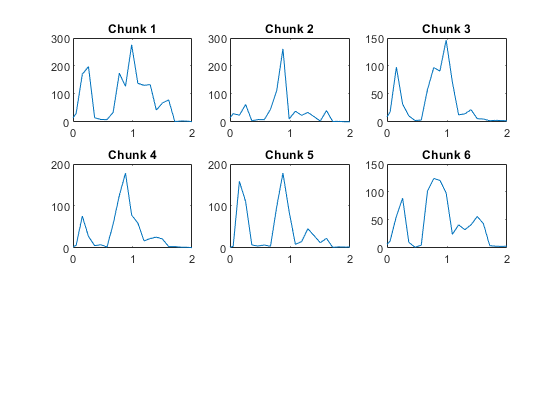

N = length(accel{1});
Fs = 55;
maxhbs = [];
figure(2);
for plotId = 1 : length(accel)
    data = accel{plotId};
    y_fft = fft(data(:, 2));
    y_fft_shift = abs(fftshift(y_fft));
    frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);
    
    breath_low = 8/60;
    breath_high = 20/60;
    hb_low = 40/60;
    hb_high = 100/60;
    
    filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
    y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/10;
    
    filter_inds = find(frequencies_shifted <= 0);
    y_fft_shift(filter_inds) = 0;

    subplot(3, 3, plotId);
    plot(frequencies_shifted, y_fft_shift) ;
    xlim([0 2])
    title(["Chunk " + plotId])
    
    range_hb =  find(hb_high >= frequencies_shifted & frequencies_shifted >= hb_low);
    range_br = find(frequencies_shifted >= breath_low & frequencies_shifted <= breath_high);
    maxhbs(plotId) = frequencies_shifted(find(y_fft_shift == max(y_fft_shift(range_hb))));
    maxbrs(plotId) = frequencies_shifted(find(y_fft_shift == max(y_fft_shift(range_br))));
end

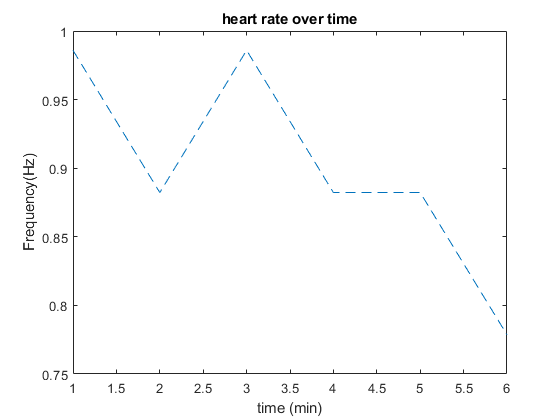


figure(3)
plot(maxhbs,"--")
title(["heart rate over time"])
ylabel(["Frequency(Hz)"])
xlabel(["time (min)"])

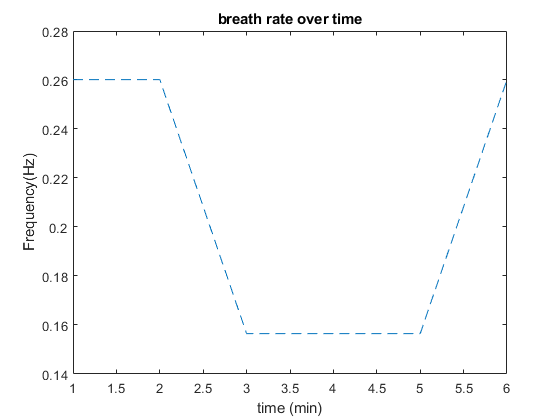


figure(4)
plot(maxbrs,"--")
title(["breath rate over time"])
ylabel(["Frequency(Hz)"])
xlabel(["time (min)"])